Sabndo que um processo de fabrico produz 30% de peças defeituosas e considerando a variavel aleatoria X, representativa do numero de peças defeituosas numa amostra de 5 peças tomadas aleatoriamente, obtenha:

Estimativa para a função massa de probabilidade de X

% Create layout
tiledlayout(2,1);

E = 1e5;
n = 5;

map = randn(n,E) < 0.3;
total = sum(map);

xi = 1:n;
p = zeros(0,n);

for i = 1:n
    p(i) = sum(total==i)/E;
end

%disp(total);

nexttile
stem(xi,p);
title('Função Massa de Probabilidade');

Grafico representativo da função distribuição acumulada de probabilidades de X

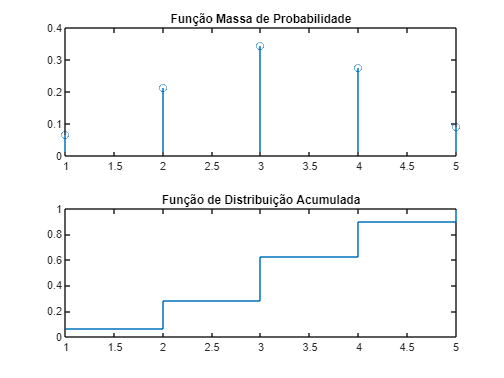

nexttile

dist = cumsum(p);
stairs(xi, dist);
title('Função de Distribuição Acumulada');

Estimativa para probabilidade de, no máximo, 2 das peças de uma amostra serem defeituosas

total2 = total < 3;

xi2 = 1:n;
p2 = zeros(0,n);
for a = 1:n
    p2(a) = sum(total2==a)/E;
end


Probabilidade de no maximo 2 peças serem defeituosas: 

prob = sum(p2);
disp(prob);

    0.2890

